syms x k pi
f_x=piecewise(-pi<=x<0,1,0<=x<=pi,0)
fplot(f_x,'LineWidth',2)
T=2*pi;
% Вычислите полупериод L
L=T/2;
% Найдите a_0, a_k, b_k
a_0=1/L*int(f_x,x,-pi,pi)
a_k=1/L*int(f_x*cos(k*x*pi/L),x,-pi,pi)
b_k=1/L*int(f_x*sin(k*x*pi/L),x,-pi,pi)
sum3 = a_0/2 + symsum(a_k*cos(k*x) + b_k*sin(k*x),k,1,3)
% pretty(sum3)
sum3 = simplify(sum3)
sum5 = a_0/2 + symsum(a_k*cos(k*x) + b_k*sin(k*x),k,1,5)
% pretty(sum5)
simplify(sum5)
sum7 = a_0/2 + symsum(a_k*cos(k*x) + b_k*sin(k*x),k,1,7)
% pretty(sum7)
simplify(sum7)
sum50 = a_0/2 + symsum(a_k*cos(k*x) + b_k*sin(k*x),k,1,50)
% pretty(sum50)
simplify(sum50)
fplot(sum3),grid, hold,
fplot(sum5)
fplot(sum7)
fplot(sum50)
fplot(f_x,'LineWidth',2)





f_x=piecewise(-1<=x<0,x+1,0<=x<1,x-1)

$$f\_x = \left\{ \begin{array}{cl} x+1 & \text{ if }x\in \left[-1,0\right)\\ x-1 & \text{ if }x\in \left[0,1\right) \end{array}\right.$$

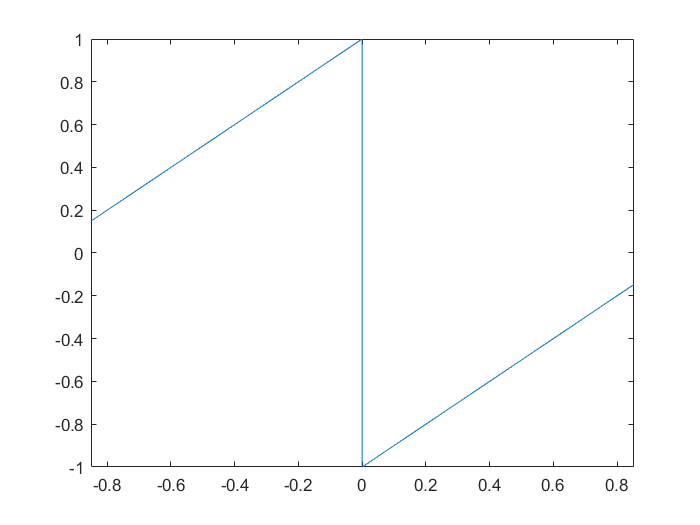

fplot(f_x)

T=2;
L=T/2;
a_0=1/L*int(f_x,x,-1,1)

$$a\_0 = 0$$

a_k=1/L*int(f_x*cos(k*x*pi/L),x,-1,1)

$$a\_k = 0$$

b_k=1/L*int(f_x*sin(k*x*pi/L),x,-1,1)

$$b\_k = \frac{2\,\left(\sin\left(\pi \,k\right)-\pi \,k\right)}{k^{2}\,\pi^{2}}$$

sum3 = a_0/L + symsum(a_k*cos(k*x*pi/L) + b_k*sin(k*x*pi/L),k,1,3)

$$sum3 = -\frac{2\,\sin\left(\pi \,x\right)}{\pi }-\frac{\sin\left(2\,\pi \,x\right)}{\pi }-\frac{2\,\sin\left(3\,\pi \,x\right)}{3\,\pi }$$

sum5 = a_0/L + symsum(a_k*cos(k*x*pi/L) + b_k*sin(k*x*pi/L),k,1,5)

$$sum5 = -\frac{2\,\sin\left(\pi \,x\right)}{\pi }-\frac{\sin\left(2\,\pi \,x\right)}{\pi }-\frac{2\,\sin\left(3\,\pi \,x\right)}{3\,\pi }-\frac{\sin\left(4\,\pi \,x\right)}{2\,\pi }-\frac{2\,\sin\left(5\,\pi \,x\right)}{5\,\pi }$$

sum7 = a_0/L + symsum(a_k*cos(k*x*pi/L) + b_k*sin(k*x*pi/L),k,1,7)

$$sum7 = -\frac{2\,\sin\left(\pi \,x\right)}{\pi }-\frac{\sin\left(2\,\pi \,x\right)}{\pi }-\frac{2\,\sin\left(3\,\pi \,x\right)}{3\,\pi }-\frac{\sin\left(4\,\pi \,x\right)}{2\,\pi }-\frac{2\,\sin\left(5\,\pi \,x\right)}{5\,\pi }-\frac{\sin\left(6\,\pi \,x\right)}{3\,\pi }-\frac{2\,\sin\left(7\,\pi \,x\right)}{7\,\pi }$$

sum50 = a_0/L + symsum(a_k*cos(k*x*pi/L) + b_k*sin(k*x*pi/L),k,1,150)

fplot(sum3),grid, hold,

Current plot held


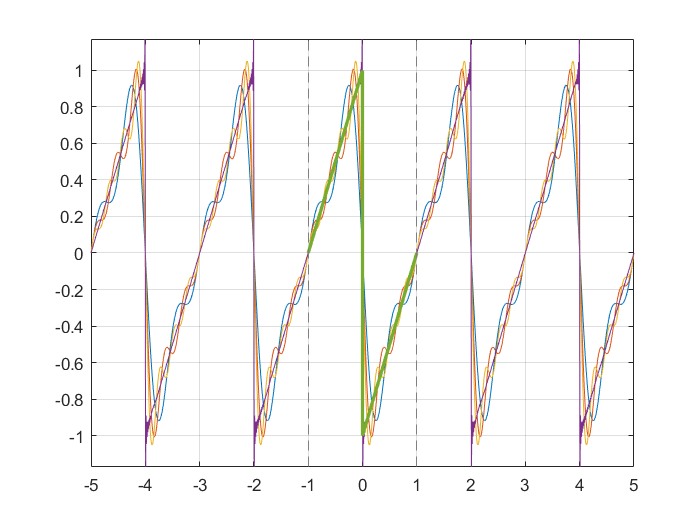

fplot(sum5)
fplot(sum7)
fplot(sum50)
fplot(f_x,'LineWidth',2)

% axis equal


figure
f_x=piecewise(-pi<=x<=0,1-x,0<x<=pi,0)

$$f\_x = \left\{ \begin{array}{cl} 1-x & \text{ if }x\in \left[-\pi ,0\right]\\ 0 & \text{ if }x\in \left(0,\pi \right] \end{array}\right.$$

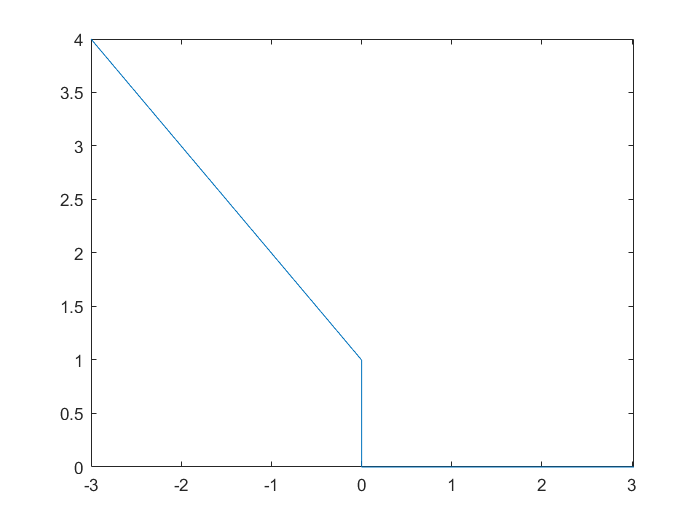


fplot(f_x)


a_0=1/pi*int(f_x,x,-pi,pi)

$$a\_0 = \frac{\pi }{2}+1$$

a_k=1/pi*int(f_x*cos(k*x),x,-pi,pi)

$$a\_k = -\frac{2\,{\sin\left(\frac{\pi \,k}{2}\right)}^{2}-k\,\left(\sin\left(\pi \,k\right)+\pi \,\sin\left(\pi \,k\right)\right)}{k^{2}\,\pi }$$

b_k=1/pi*int(f_x*sin(k*x),x,-pi,pi)

$$b\_k = \frac{\frac{\cos\left(\pi \,k\right)-1}{k}-\frac{\sin\left(\pi \,k\right)-\pi \,k\,\cos\left(\pi \,k\right)}{k^{2}}}{\pi }$$

sum3 = a_0/2 + symsum(a_k*cos(k*x) + b_k*sin(k*x),k,1,3);
sum5 = a_0/2 + symsum(a_k*cos(k*x) + b_k*sin(k*x),k,1,5);
sum7 = a_0/2 + symsum(a_k*cos(k*x) + b_k*sin(k*x),k,1,7);
sum50 = a_0/2 + symsum(a_k*cos(k*x) + b_k*sin(k*x),k,1,50);
fplot(sum3),grid, hold,

Current plot held


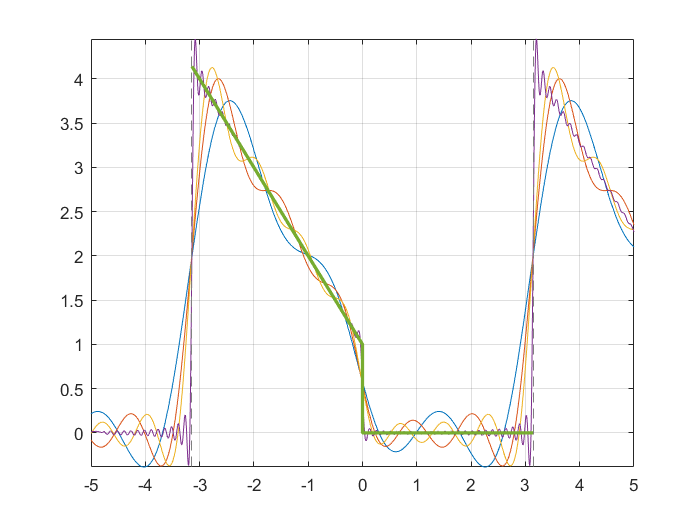

fplot(sum5)
fplot(sum7)
fplot(sum50)
fplot(f_x,'LineWidth',2)

% axis equal


figure
f_x=piecewise(-3<x<=0,-2,0<+x<3,3-x)

$$f\_x = \left\{ \begin{array}{cl} -2 & \text{ if }x\in \left(-3,0\right]\\ 3-x & \text{ if }x\in \left(0,3\right) \end{array}\right.$$

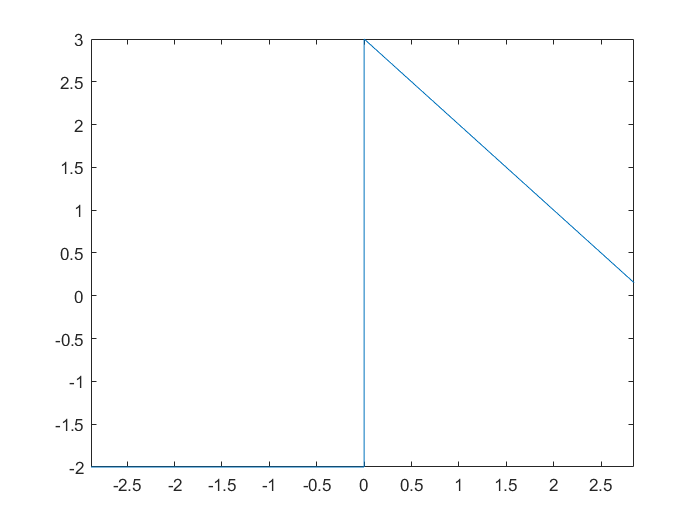


fplot(f_x)


a_0=1/3*int(f_x,x,-3,3)

$$a\_0 = -\frac{1}{2}$$

a_k=1/3*int(f_x*cos(k*x),x,-3,3)

$$a\_k = -\frac{2\,\sin\left(3\,k\right)}{3\,k}-\frac{\cos\left(3\,k\right)-1}{3\,k^{2}}$$

b_k=1/3*int(f_x*sin(k*x),x,-3,3)

$$b\_k = \frac{3\,k-\sin\left(3\,k\right)}{3\,k^{2}}-\frac{2\,\left(\cos\left(3\,k\right)-1\right)}{3\,k}$$

sum3 = a_0/2 + symsum(a_k*cos(k*x) + b_k*sin(k*x),k,1,3);
sum5 = a_0/2 + symsum(a_k*cos(k*x) + b_k*sin(k*x),k,1,5);
sum7 = a_0/2 + symsum(a_k*cos(k*x) + b_k*sin(k*x),k,1,7);
sum50 = a_0/2 + symsum(a_k*cos(k*x) + b_k*sin(k*x),k,1,50);
fplot(sum3),grid, hold,

Current plot held


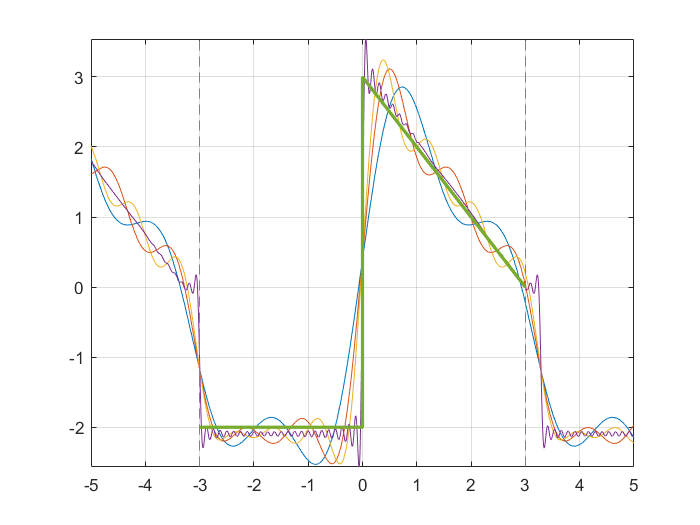

fplot(sum5)
fplot(sum7)
fplot(sum50)
fplot(f_x,'LineWidth',2)

% axis equal


figure
f_x=piecewise(-pi<=x<=pi,x+1)

$$f\_x = \left\{ \begin{array}{cl} x+1 & \text{ if }x\in \left[-\pi ,\pi \right] \end{array}\right.$$

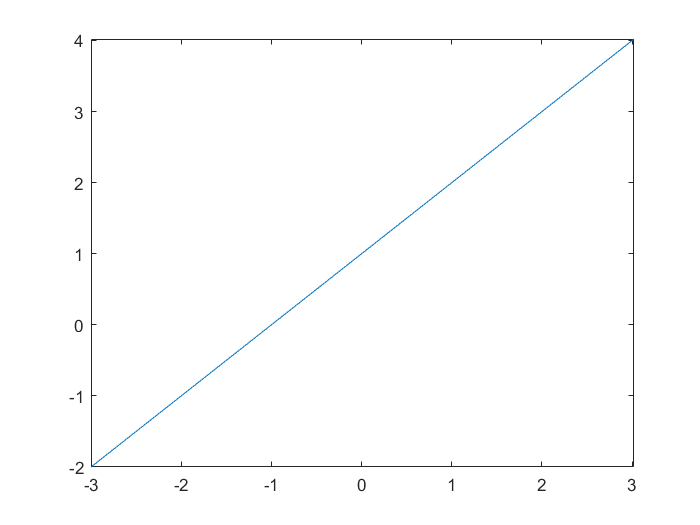

fplot(f_x)


a_0=1/pi*int(f_x,x,-pi,pi)

$$a\_0 = 2$$

a_k=1/pi*int(f_x*cos(k*x),x,-pi,pi)

$$a\_k = \frac{2\,\sin\left(\pi \,k\right)}{k\,\pi }$$

b_k=1/pi*int(f_x*sin(k*x),x,-pi,pi)

$$b\_k = \frac{2\,\left(\sin\left(\pi \,k\right)-\pi \,k\,\cos\left(\pi \,k\right)\right)}{k^{2}\,\pi }$$

sum3 = a_0/2 + symsum(a_k*cos(k*x) + b_k*sin(k*x),k,1,3);
sum5 = a_0/2 + symsum(a_k*cos(k*x) + b_k*sin(k*x),k,1,5);
sum7 = a_0/2 + symsum(a_k*cos(k*x) + b_k*sin(k*x),k,1,7);
sum50 = a_0/2 + symsum(a_k*cos(k*x) + b_k*sin(k*x),k,1,50);
fplot(sum3),grid, hold,

Current plot held


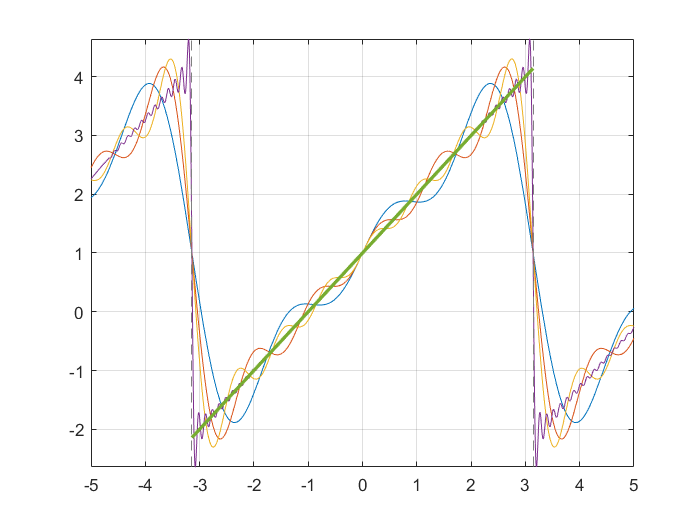

fplot(sum5)
fplot(sum7)
fplot(sum50)
fplot(f_x,'LineWidth',2)

% axis equal